c)

(iii) Generalize your code to solve the problem with $h=\frac{1}{20}$


$$n=\frac{1}{h}-1=19$$


For matrix K, it can be determine by generate (1/h)*Kn matrix

For vector F:

$F=4v\left(1\right)-\int_0^1 \textrm{fvdx}$                (1)

With $h=\frac{1}{20}$, there will be 19 hat function and 1 half hat function

So $4v\left(1\right)$will be 0 except the last term.

For each hat function, suppose that setting the center of each hat function as nh, n=1,2,...19

Three point are needed:


$$\begin{array}{l}
\left(\left(n-1\right)h,0\right)\\
\left(\textrm{nh},1\right)\\
\left(\left(n+1\right)h,0\right)
\end{array}$$


For function$y=\textrm{mx}+b$at the left side of hat function


$$0=m\left(n-1\right)h+b$$



$$1=\textrm{mnh}+b$$



$$\begin{array}{l}
\textrm{mnh}-m\left(n-1\right)h=1\\
\textrm{mnh}-\textrm{mhn}+\textrm{mh}=1\\
\textrm{mh}=1\\
m=\frac{1}{h}
\end{array}$$



$$\begin{array}{l}
1=\frac{1}{h}\textrm{nh}+b\\
1=n+b\\
b=1-n
\end{array}$$



$$y_1 =\frac{1}{h}x+1-n$$


For function$y=\textrm{mx}+b$at the right side of hat function


$$1=\textrm{mnh}+b$$



$$0=m\left(n+1\right)h+b$$



$$\begin{array}{l}
\textrm{mhn}-m\left(n+1\right)h=1\\
\textrm{mhn}-\textrm{mhn}-\textrm{mh}=1\\
\textrm{mh}=-1\\
m=-\frac{1}{h}
\end{array}$$



$$\begin{array}{l}
1=-\frac{1}{h}\textrm{hh}+b\\
1=-n+b\\
b=1+n
\end{array}$$



$$y_2 =-\frac{1}{h}x+1+n$$


Therefore

$\begin{array}{l}
\int_0^1 \textrm{fvdx}=\int_{\left(n-1\right)h}^{\textrm{nh}} \left(x-2\right)\left(\frac{1}{h}x+1-n\right)\textrm{dx}+\int_{\textrm{nh}}^{\left(n+1\right)h} \left(x-2\right)\left(-\frac{1}{h}x+1+n\right)\textrm{dx}\\
=\frac{h\left(3\textrm{hn}-h-6\right)}{6}+\frac{h\left(3\textrm{hn}+h-6\right)}{6}\\
=\frac{h\left(3\textrm{hn}-h-6\right)+h\left(3\textrm{hn}+h-6\right)}{6}\\
=\frac{h\left(3\textrm{hn}-h-6+3\textrm{hn}+h-6\right)}{6}\\
=\frac{h\left(3\textrm{hn}-6+3\textrm{hn}-6\right)}{6}\\
=\frac{h\left(6\textrm{hn}-12\right)}{6}
\end{array}$                (2)

for n=1,2,...,19

h=1/20

Also for the half hat:

$\begin{array}{l}
b=\int_0^1 \textrm{fvdx}=\int_{\left(n-1\right)h}^{\textrm{nh}} \left(x-2\right)\left(\frac{1}{h}x+1-n\right)\textrm{dx}\\
B_{20} =\frac{h\left(3\textrm{hn}-h-6\right)}{6}
\end{array}$                                                            (3)

So for the hat function

F vector is

$\begin{array}{l}
4v\left(1\right)-\int_0^1 \textrm{fvdx}\\
=\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
\frac{h\left(6h-12\right)}{6}\\
\frac{h\left(6\textrm{h2}-12\right)}{6}\\
\frac{h\left(6\textrm{h3}-12\right)}{6}\\
\vdots \\
\frac{h\left(6\textrm{h19}-12\right)}{6}\\
\frac{h\left(3\textrm{h20}-h-6\right)}{6}
\end{array}\right\rbrack 
\end{array}$                (4)

clear

h=1/20;%define h
n=1/h-1;%compute n
e = ones(n+1, 1);

%generate Kn
K = spdiags([-e, 2*e, -e], -1:1, n+1, n+1);
K(n+1,n+1)=1;
K=K*(n+1);

%generate v
v=zeros(1,n+1);
v(end)=1;

%generate b vector 1 to 19 by equation (2)
b=zeros(1,n+1);
for i=1:n
    b(i)=h*(6*h*i-12)/6;
    %equation (2)
end
bn=n+1;
b(end)=h*(3*h*bn-h-6)/6;%equation (3)

F=4*v-b;%equation (4)
F=F';
coe = K\F;%solve u
coe = [0;coe]

coe =          0
    0.2725
    0.5402
    0.8031
    1.0613
    1.3151
    1.5645
    1.8096
    2.0507
    2.2877



x = linspace(0, 1, 100);%define x
xg = linspace(0,1,n + 2);%true x with n+1 points
up = realf(xg);%true value of the grid
u = realf(x);%true solution

error=abs(coe(:) - up(:))%compute the error

error = 	1.0e+-14 *

         0
    0.0278
    0.0555
    0.0666
    0.0888
    0.1110
    0.1332
    0.1554
    0.0888
    0.1332


error is still to the order of -14

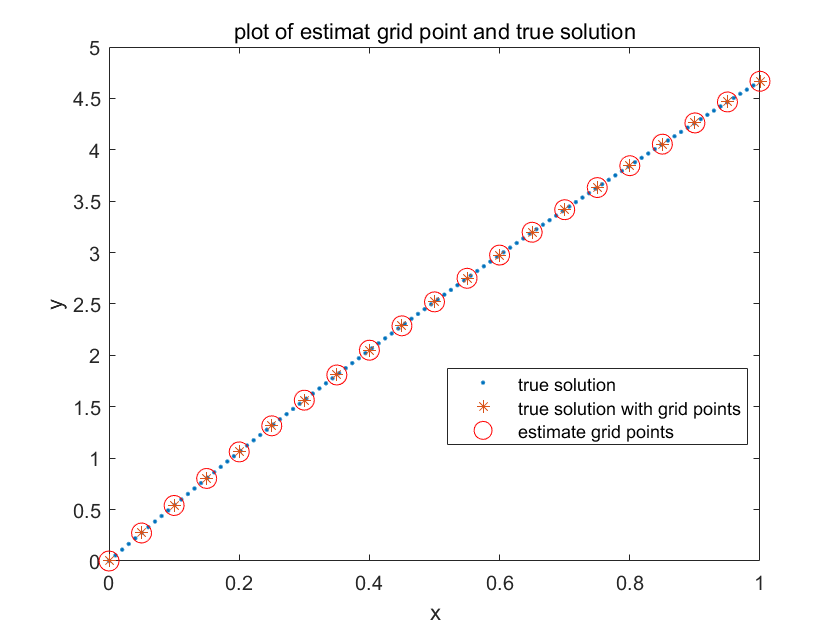

%plot
plot(x, u, '.')
hold on
plot(xg, up, '*')
plot(xg, coe, 'o', 'Markersize', 10, 'Color','r')
legend('true solution', 'true solution with grid points', 'estimate grid points','Location','best')
xlabel('x')
ylabel('y')
title('plot of estimat grid point and true solution')
hold off

function [r]=realf(x)
%Function of compute the true value for comparison. from (a)
    r = 1/6*x.^3 - x.^2+11/2*x;
end
